# XGLO single unit bench

## Adding functions to path

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


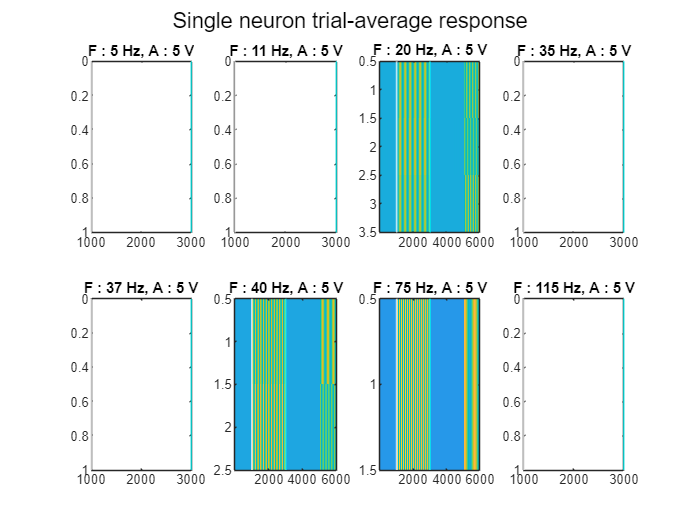

figure;

Flist = [5, 11, 20, 35, 37, 40, 75, 115];
Alist = [3, 4, 5];

for i = 17:24

    idx = mod(i-1, 8) + 1;
    idy = ceil(i / 8);

    img = squeeze(a{i});

    for ik = 1:size(img, 1)

        img(ik, :) = (img(ik, :) - mean(img(ik, :))) / (std(img(ik, :))*sqrt(size(a{i}, 1)));

    end

    img(isnan(img)) = 0;
    subplot(2, 4, idx);
    imagesc(img);
    clim([-2.5 2.5]);
    xline(1000, "Color", [1 1 1], "LineWidth", 1);
    xline(3000, "Color", [0 1 1], "LineWidth", 1);

    title("F : " + num2str(Flist(idx)) + " Hz, A : " + num2str(Alist(idy)) + " V");

end

sgtitle("Single neuron trial-average response");

## Loading single unit partitioned files

xunits = load("data\xunits_conv.mat", "xunits");
xunits = xunits.xunits;

## Responses (PFC)

aaab = squeeze(mean(xunits{4, 1}.sigsb2l, 1));
aaax = squeeze(mean(xunits{4, 1}.sigsb2o4, 1));
axab = squeeze(mean(xunits{4, 1}.sigsb2o2, 1));

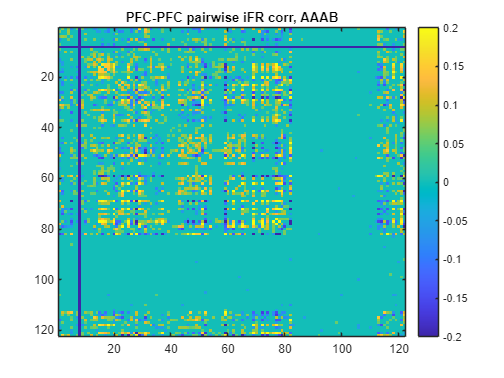

rh = corr(squeeze(aaab)', squeeze(aaab)', "Type", "Spearman");
rh(abs(rh) > 0.9) = 0;
rh(abs(rh) < 0.05) = 0;

figure;
imagesc(rh);title("PFC-PFC pairwise iFR corr, AAAB");
clim([-0.2 0.2]);
colorbar();

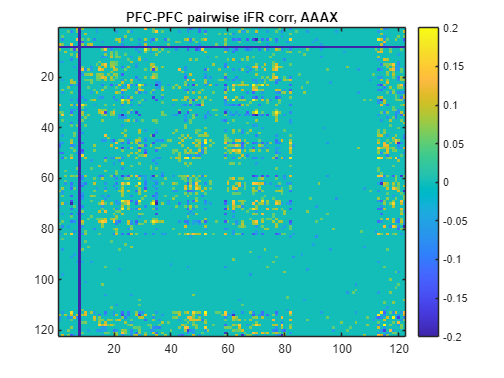

rh = corr(squeeze(aaax)', squeeze(aaax)', "Type", "Spearman");
rh(abs(rh) > 0.9) = 0;
rh(abs(rh) < 0.05) = 0;

figure;
imagesc(rh);title("PFC-PFC pairwise iFR corr, AAAX");
clim([-0.2 0.2]);
colorbar();

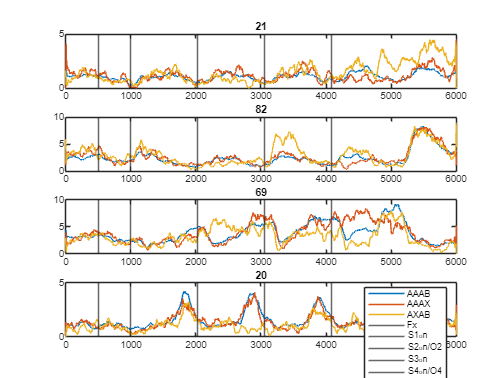

unx = 21;
figure;
subplot(4, 1, 1);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 82;
subplot(4, 1, 2);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 69;
subplot(4, 1, 3);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 20;
subplot(4, 1, 4);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

legend();

## Responses (FEF)

aaab = squeeze(mean(xunits{4, 1}.sigsb2l, 1));
aaax = squeeze(mean(xunits{4, 1}.sigsb2o4, 1));
axab = squeeze(mean(xunits{4, 1}.sigsb2o2, 1));

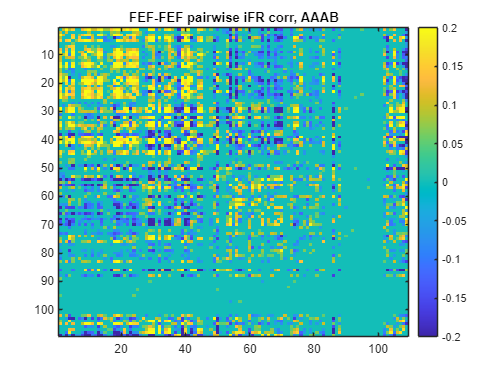

rh = corr(squeeze(aaab)', squeeze(aaab)', "Type", "Spearman");
rh(abs(rh) > 0.9) = 0;
rh(abs(rh) < 0.05) = 0;

figure;
imagesc(rh);title("FEF-FEF pairwise iFR corr, AAAB");
clim([-0.2 0.2]);
colorbar();

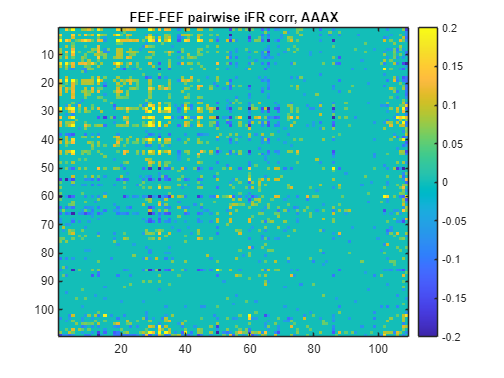

rh = corr(squeeze(aaax)', squeeze(aaax)', "Type", "Spearman");
rh(abs(rh) > 0.9) = 0;
rh(abs(rh) < 0.05) = 0;

figure;
imagesc(rh);title("FEF-FEF pairwise iFR corr, AAAX");
clim([-0.2 0.2]);
colorbar();

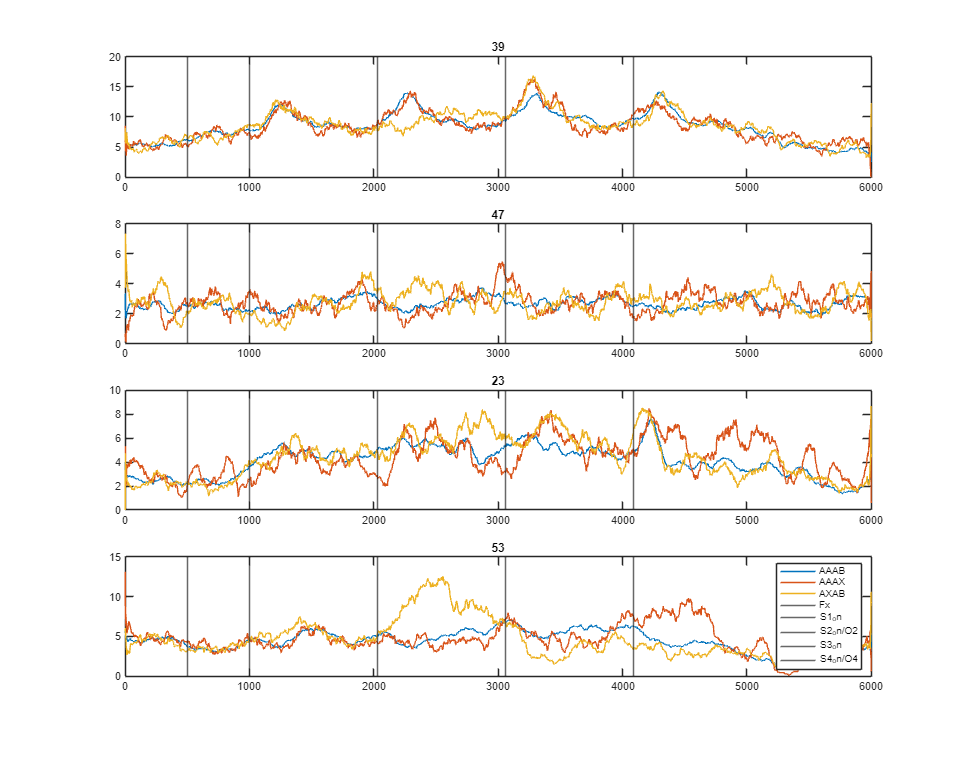

unx = 39;
figure("Position", [0 0 1900 1500]);
subplot(4, 1, 1);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 47;
subplot(4, 1, 2);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 23;
subplot(4, 1, 3);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 53;
subplot(4, 1, 4);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

legend();

## Responses (PFC)

aaab = squeeze(mean(xunits{5, 1}.sigsb2l, 1));
aaax = squeeze(mean(xunits{5, 1}.sigsb2o4, 1));
axab = squeeze(mean(xunits{5, 1}.sigsb2o2, 1));

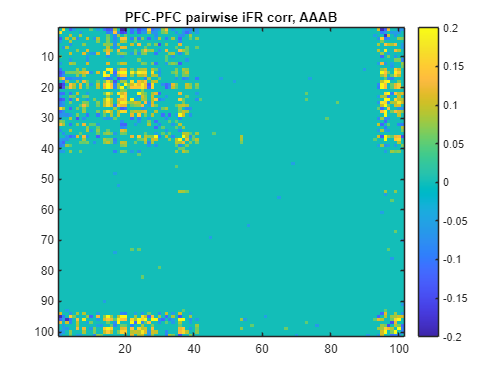

rh = corr(squeeze(aaab)', squeeze(aaab)', "Type", "Spearman");
rh(abs(rh) > 0.9) = 0;
rh(abs(rh) < 0.05) = 0;

figure;
imagesc(rh);title("PFC-PFC pairwise iFR corr, AAAB");
clim([-0.2 0.2]);
colorbar();

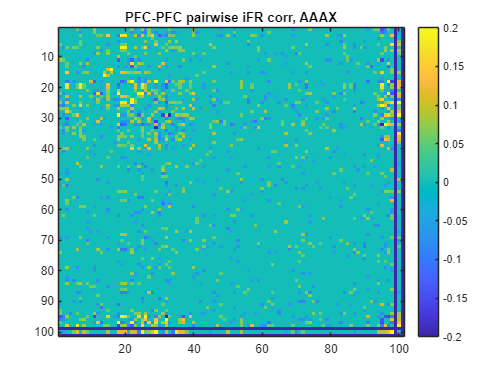

rh = corr(squeeze(aaax)', squeeze(aaax)', "Type", "Spearman");
rh(abs(rh) > 0.9) = 0;
rh(abs(rh) < 0.05) = 0;

figure;
imagesc(rh);title("PFC-PFC pairwise iFR corr, AAAX");
clim([-0.2 0.2]);
colorbar();

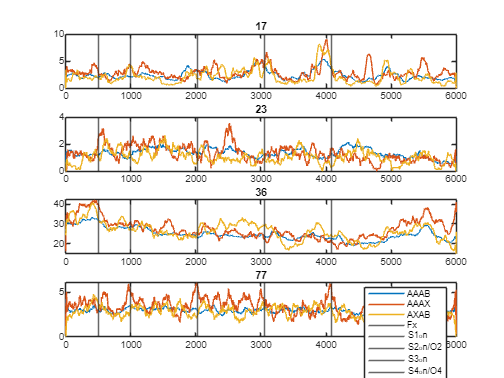

unx = 17;
figure;
subplot(4, 1, 1);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 23;
subplot(4, 1, 2);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 36;
subplot(4, 1, 3);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

unx = 77;
subplot(4, 1, 4);
plot(smooth(aaab(unx, :), 100), "DisplayName", "AAAB");
hold("on");
plot(smooth(aaax(unx, :), 100), "DisplayName", "AAAX");
plot(smooth(axab(unx, :), 100), "DisplayName", "AXAB");
xline(500, "DisplayName", "Fx");
xline(1000, "DisplayName", "S1_on");
xline(2030, "DisplayName", "S2_on/O2");
xline(3060, "DisplayName", "S3_on");
xline(4090, "DisplayName", "S4_on/O4");
title(unx);

legend();

hFig = figure('Name', 'Single unit analysis / OGLO passive', 'NumberTitle', 'off');
hT = uitabgroup('Parent', hFig);
hTabs = cell(1);
cnt = 1;

for i = 1:10

    title_ = "N" + num2str(i*12 - 11) + " - " + num2str(i*12);
    hTabs{cnt} = uitab('Parent', hT, 'Title', title_);
    axes('Parent', hTabs{cnt});
    t = linspace(-1000, 5000, 6000);
    y = squeeze(mean(xunits{3, 1}.sigsb2l, 1));

    for ij = 1:12
    
        subplot(3, 4, ij);
        plot(t, y(i*12 -12 + ij, :));

    end

    cnt = cnt + 1;

end

## End